labelCount = 32×2 table
    Label    Count
    _____    _____

      2      1495 
      3      1500 
      4      1518 
      5      1551 
      6      1459 
      7      1564 
      8      1509 
      9      1378 
      A      1208 
      B      1473 
      C      1540 
      D      1495 
      E      1535 
      F      1489 
      G      1536 
      H      1254 


ans =     28    28


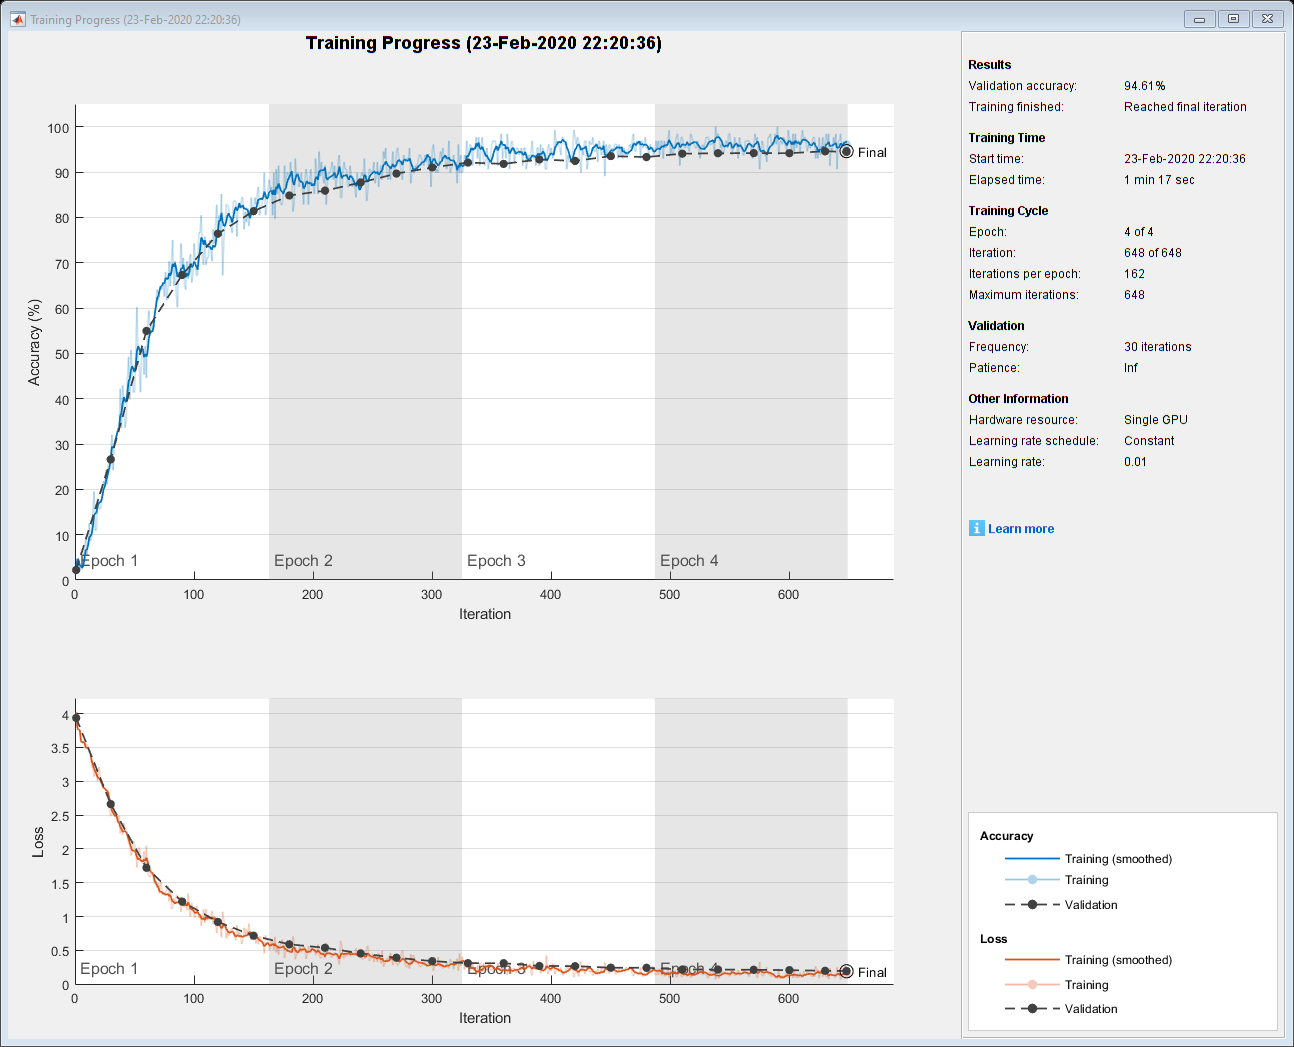

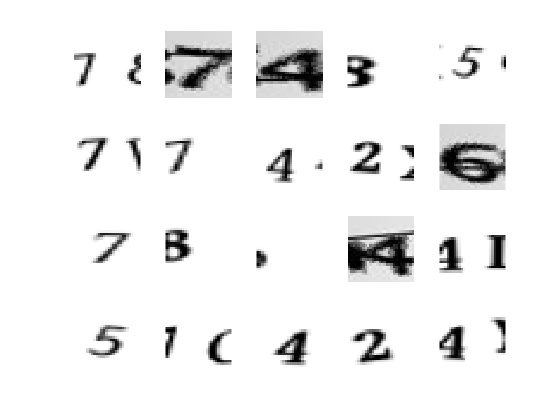

accuracy = 0.9522

clear all;
if ~isfile('CNN_net.mat')
    digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
        'nndatasets','DigitDataset');
    imds = imageDatastore('split_images_CNN', ...
        'IncludeSubfolders',true, ...
        'LabelSource','foldernames');
    figure;
    perm = randperm(10000,20);
    for i = 1:20
        subplot(4,5,i);
        imshow(imds.Files{perm(i)});
    end
    labelCount = countEachLabel(imds)
    img = readimage(imds,1);
    size(img)
    numTrainFiles = 650;
    numTestingFiles = 100;
    [imdsTrain,imdsTest,imdsValidation] = splitEachLabel(imds,numTrainFiles,numTestingFiles,'randomize');
    layers = [
        imageInputLayer([28 28 1])
        
        convolution2dLayer(3,8,'Padding','same')
        batchNormalizationLayer
        reluLayer
        
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(3,16,'Padding','same')
        batchNormalizationLayer
        reluLayer
        
        maxPooling2dLayer(2,'Stride',2)
        
        convolution2dLayer(3,32,'Padding','same')
        batchNormalizationLayer
        reluLayer
        
        fullyConnectedLayer(32)
        softmaxLayer
        classificationLayer];
    options = trainingOptions('sgdm', ...
        'InitialLearnRate',0.01, ...
        'MaxEpochs',4, ...
        'Shuffle','every-epoch', ...
        'ValidationData',imdsValidation, ...
        'ValidationFrequency',30, ...
        'Verbose',false, ...
        'Plots','training-progress');
    net = trainNetwork(imdsTrain,layers,options);
    YPred = classify(net,imdsTest);
    YTest = imdsTest.Labels;
    accuracy = sum(YPred == YTest)/numel(YTest)
    save('CNN_net.mat', 'net')
else
    load('CNN_net.mat')
end